# Plotting the number of contributions in NNs per application per year

% Specify the Excel file name (replace with your file name)
filename = '3_count_per_application_and_year.xlsx';

% Read the Excel file into a table
dataTable = readtable(filename);
% Display the imported data
disp('Imported Table:');

Imported Table:


disp(dataTable);

         Application          Year    Count
    ______________________    ____    _____

    {'Bio-implementation'}    2017      1  
    {'Bio-implementation'}    2018      1  
    {'Bio-implementation'}    2019      1  
    {'Bio-implementation'}    2021      5  
    {'Bio-implementation'}    2022      5  
    {'Bio-implementation'}    2023      4  
    {'Bio-implementation'}    2024      4  
    {'Dataset generation'}    2017      3  
    {'Dataset generation'}    2018      2  
    {'Dataset generation'}    2019      5  
    {'Dataset generation'}    2020      3  
    {'Dataset generation'}    2021      2  
    {'Dataset generation'}    2022      5  
    {'Dataset generation'}    2023      7  
    {'Dataset generation'}    2024      2  
    {'Explainability'    }    2021      1  
    {'Explainability'    }    2023      2  
    {'Explainability'    }    2024      1  
    {'MAC layer' 


% Find unique application entries
apps = unique(dataTable{:,1});
disp('Application entries:');

Application entries:


%switching entries
temp=apps{5};
apps{5}=apps{4};
apps{4}=temp;
disp(apps);

    {'Bio-implementation'}
    {'Dataset generation'}
    {'Explainability'    }
    {'PHY layer'         }
    {'MAC layer'         }
    {'Upper layers'      }



% Find unique years
years = unique(dataTable{:,2});
disp('Years:');

Years:


disp(years);

        2017
        2018
        2019
        2020
        2021
        2022
        2023
        2024




% Conforming a matrix where the rows refers to the applications and the
% columns refer to the year
app_per_year=zeros(numel(apps),numel(years));
% filling in the table
for i=1:numel(apps)%loop per application
    for j=1:numel(years)%loop per year
        %looking for the corresponding entry in the table
        idx=ismember(dataTable{:,1},apps{i}) & ismember(dataTable{:,2},years(j));
        idx_app_per_year=find(idx==1);
        %filling the data out
        if(~isempty(idx_app_per_year))
            app_per_year(i,j)=dataTable{idx_app_per_year,3};
        end
    end
end

% implementing the cumulative vie
app_per_year_cum=cumsum(app_per_year,2);

### Bar plot

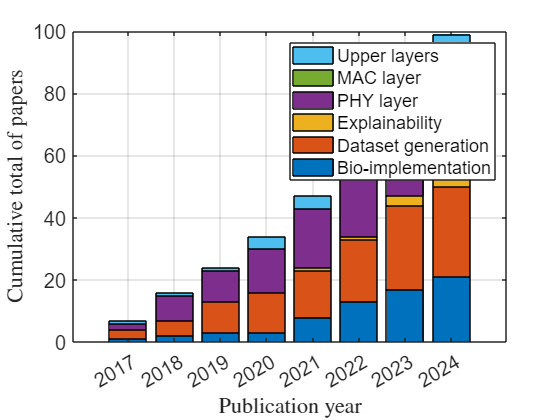

fontsize=15; %for plotting
figure;
bar(years,app_per_year_cum','stacked'); grid on;
xlabel('Publication year','Interpreter','latex');
ylabel('Cumulative total of papers','Interpreter','latex');
set(gca,'FontSize',fontsize);
legend(apps);